# Laborübung 3

## Laurenz Hundgeburth und Gregor Fritz

Im Rahmen dieser Laborübung soll das erworbene Wissen in der digitalen Regelungtechnik vertieft werden. Dazu werden grundsätzlich die aus den vorhergehenden Laborübungen entworfenen Regler in digitaler Form realisiert und implementiert. Dabei werden Kenntnisse über Aufbau, Komponenten und Arbeitsweise eines digitalen Regelkreises erarbeitet. Zunächst werden die wesentlichen Komponenten des betrachteten digitalen Regelkreises beschrieben.

## 3.1 Aufbau und Test der Hardware

Erstellen Sie, wie in Abbildung 3.4 ersichtlich, den benötigten Hardwareaufbau auf dem zu Verfügung gestellten Steckbrett. Bevor nun Algorithmen auf der eigentlichen Hardware implementiert und getestet werden konnen, müssen zuerst geeeignete Bausteine gewählt werden, um das eigentliche System anzusteuern und die Funktionalität aller Komponenten des mechatronischen Systems sicher zu stellen. Die Auswertung des Encoder-Signals wird auf der Hardware durch Interrupt-Signale implementiert. Jede steigende und fallende Flanke auf den Signalen A und B erzeugt einen Aufruf der Interrupt-Routine. Folgende Grafik gibt einen Überblick über die Funktionsweise von Quadratur-Signalen:

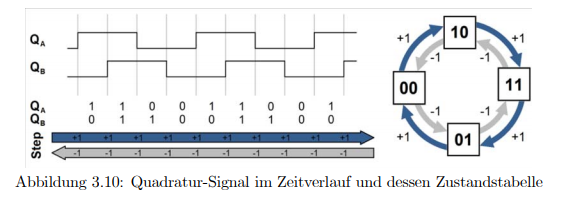

## a) Zeitverlauf des Quadratur-Signales

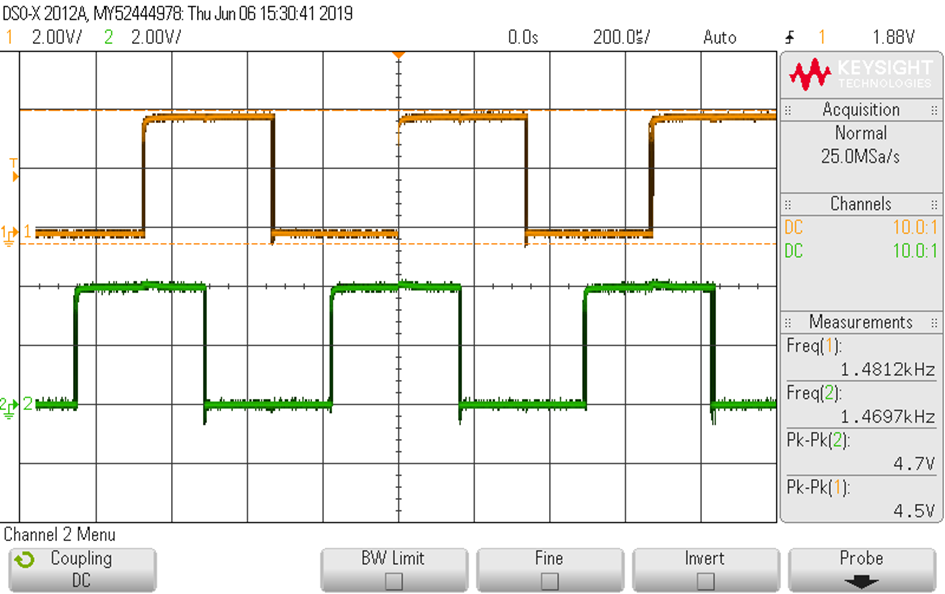

-> Das Oszilloskop zeigt den gleichen Signalverlauf wie Abb. 3.10 der Aufgabenstellung. Die beiden Signale haben die gleiche Frequenz und sind 90° zueinander versetzt. 

## b) Erfassung der Quadratur-Impulse

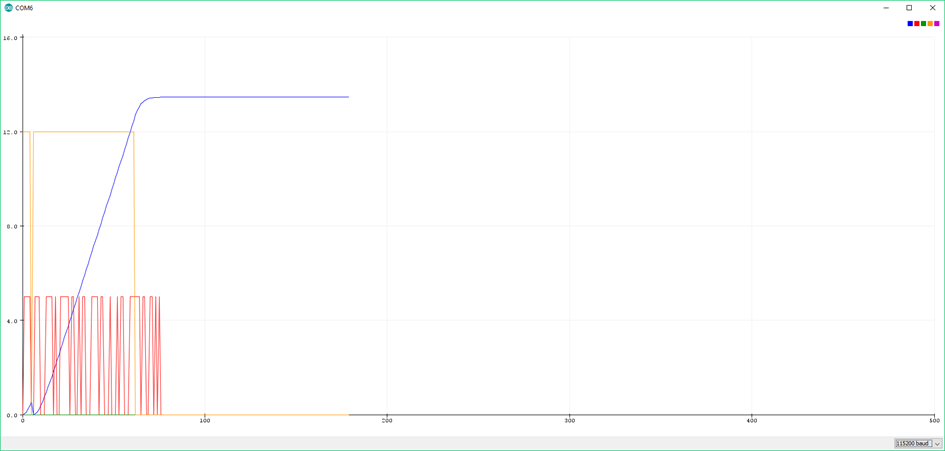

-> Bei dieser Übung haben wir nur die Stärke des Motors und wie weit er sich drehen soll eingestellt. Der Motor hat sich genau so verhalten wie erwartet, nachdem er seine endgültige Position von 2 Umdrehungen erreicht hatte, hat er die Spannung auf 0 gesetzt und damit den Motor nicht mehr angetrieben. Da noch kein Regler implementiert worden war, drehte sich der Servo-Arm durch die Trägheit noch um etwa 60° weiter. 

## 3.2 Motor-Ansteuerung

Der Motor wird mithilfe eines PWM-Signales angesteuert. Überprüfen Sie das PWM Signal des Motors wiederum mit einem Oszilloskop. Nehmen Sie unterschiedliche Messungen dazu auf.

## a) PWM Messung 5V

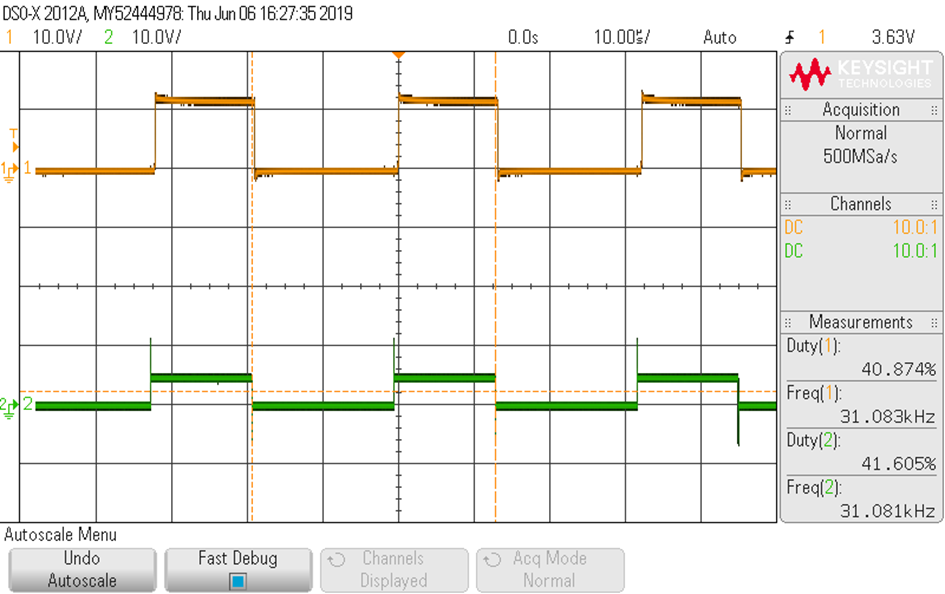

-> Bei 5 Volt bekommt man einen Duty-Cycle von $\frac{100}{12V}*5V=41,66%$

Damit man auf eine konstante Spannung von 5 Volt kommt, steuert man den Motor mit den maximalen 12 Volt an, allerdings nur 41,66% einer Periode.  

Messungen mit dem Multimeter:

Leitung M2: 4,93 Volt

PWM : 1,91 Volt

## b) PWM Messung 1V

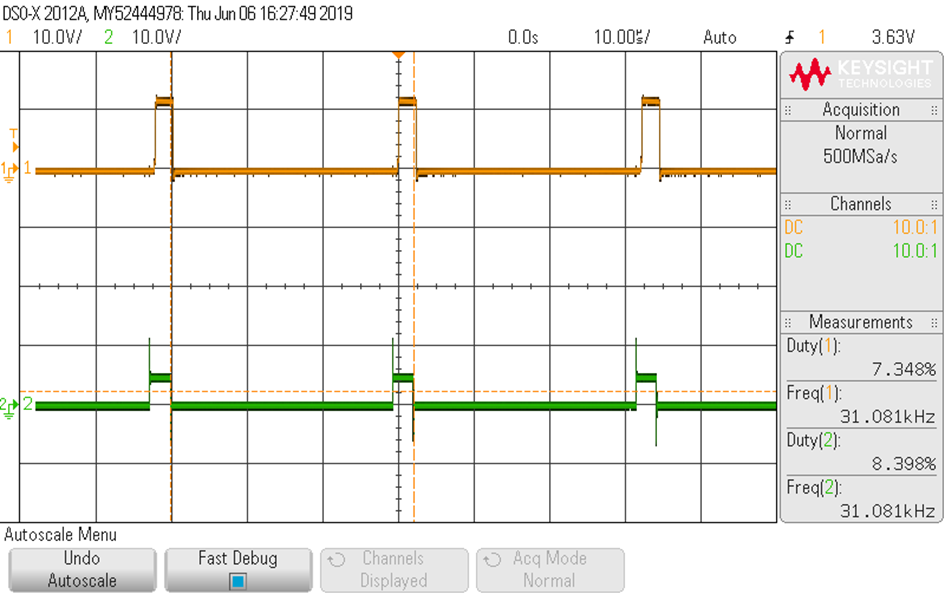

-> Bei 1 Volt bekommt man einen Duty-Cycle $\frac{100}{12V}*1V=8,33%$

Messungen mit dem Multimeter:

Leitung M2: 0,81 Volt

PWM : 0,38 Volt

## 3.3 Digitaler P-Regler

## a)

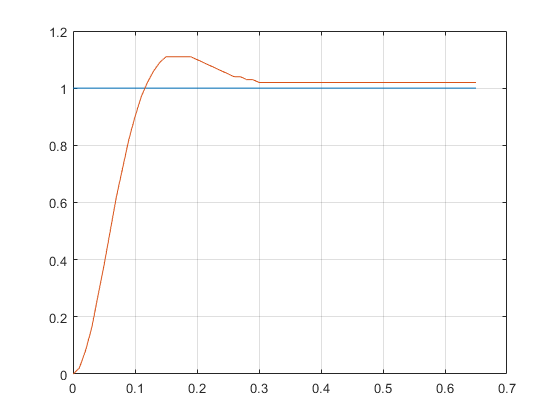

plot_txt('3_3_a.txt');

## b)

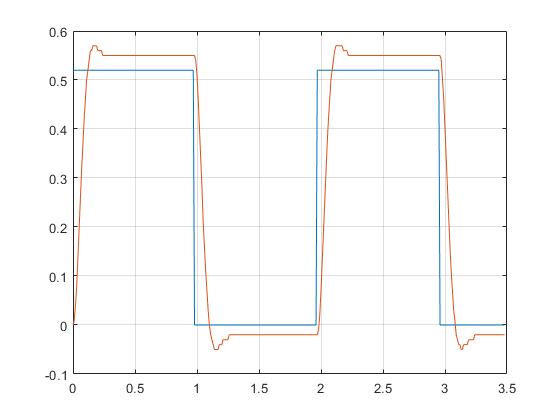

plot_txt('3_3_b.txt');

## c)

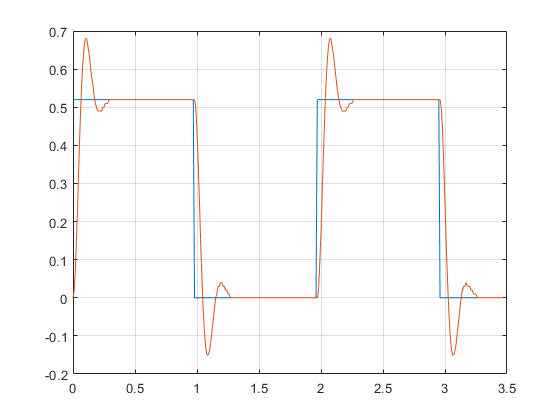

plot_txt('3_3_c_2kp.txt');

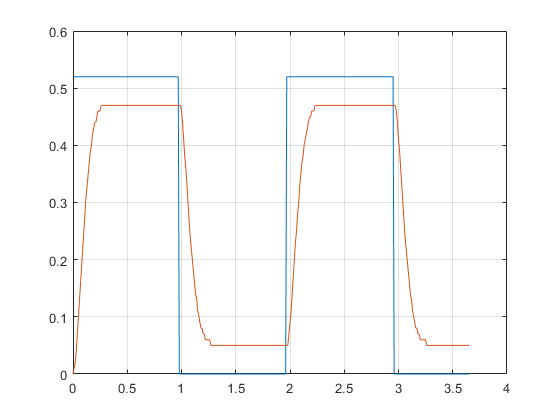

plot_txt('3_3_c_05kp.txt');

## 3.4 Digitaler Regler - FKL Verfahren

## b)

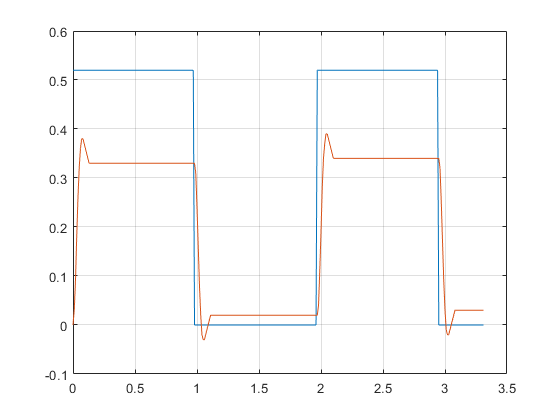

plot_txt('3_4_a.txt');

## c)

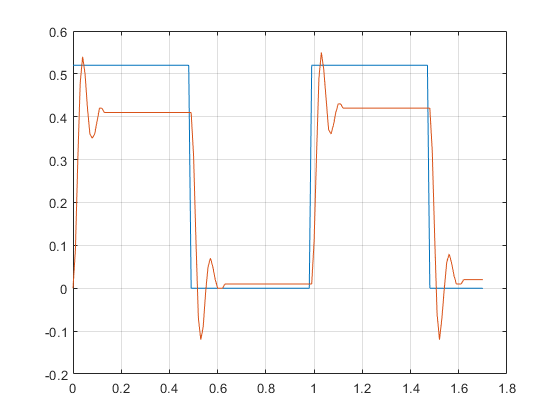

plot_txt('3_4_c_20.txt');

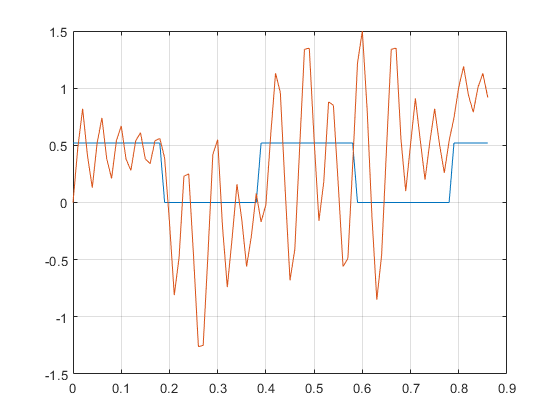

plot_txt('3_4_c_50.txt');

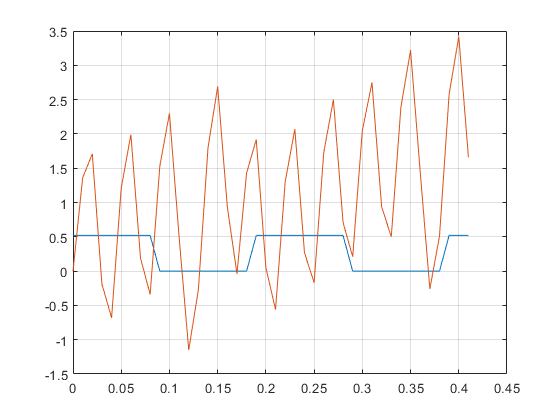

plot_txt('3_4_c_100.txt');

## 3.5 Digitaler integrierender Regler

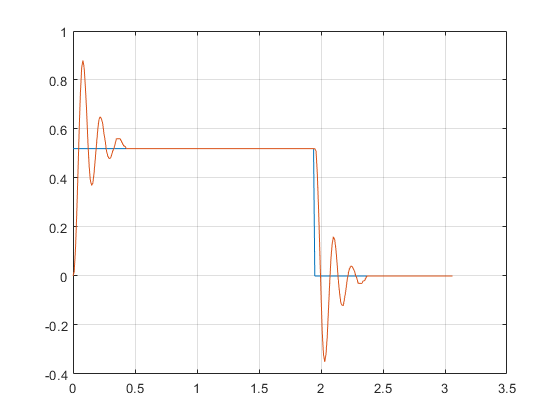

plot_txt('3_5_a.txt');

function plot_txt(path)
data10mS = read_control_to_workspace(path);
t10mS = 0:0.010:(size(data10mS.y) -1) * 0.010;

figure()
plot(t10mS, data10mS.r, t10mS, data10mS.y);grid
end